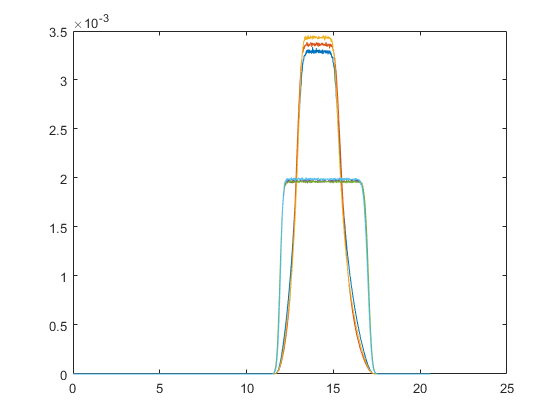

ans = '.'

ans = '..'

ans = 'tempDTn_1.00e-01_0.00.output'

ans = 'tempDTn_1.00e-01_0.00_HS.output'

ans = 'tempDTn_1.00e-01_1.00.output'

ans = 'tempDTn_1.00e-02_0.00.output'

ans = 'tempDTn_1.00e-02_0.00_HS.output'

ans = 'tempDTn_1.00e-02_1.00.output'

figure; hold on; box on;
files = dir();


for i = 1:length(files)
    
    files(i).name
    
    if contains(files(i).name, ".output") && contains(files(i).name, "DTn")
        
        data = getData(files(i).name);
        plot(data.energy, data.value./sum(data.value), 'DisplayName',files(i).name)
        
    end
end

function data = getData(filename)

    file = fopen(filename);
    while ~feof(file)
        
        line = fgetl(file);
        
        if contains(line, "--- Birth Spectrum Tally ---")
            
            line = fgetl(file);
            line = fgetl(file);
            line = fgetl(file);
            
            energy = []; value = []; unc = [];
            done = false;
            while ~done
                
               temp = strsplit(line, ",");
               
               energy(end+1) = str2double(temp{1});
               value(end+1)  = str2double(temp{2});
               unc(end+1)    = str2double(temp{3});
               
               line = fgetl(file);
               done = contains(line, "total");
               
            end
        end
    end
    
    fclose(file);
    
    data = [];
    data.energy = energy;
    data.value = value;
    data.unc = unc;

end